
syms theta_1 phi_1 phi_2;

a = 2.1; b = 1.6; c = 2.6; d = 0.9;

const1 = (a*cos(theta_1)) + (b*cos(theta_1+phi_1)) - d - (c*cos(phi_2));
const2 = (a*sin(theta_1)) + (b*sin(theta_1+phi_1)) - (c*sin(phi_2));

cons = [const1;const2];

jacU = [diff(const1,phi_1) diff(const1,phi_2);diff(const2,phi_1) diff(const2,phi_2)];
jacV = [diff(const1,theta_1);diff(const2,theta_1)];
q_init_u = [0.2;0.4];

omega = 1; %rad/sec
time = transpose(0:0.05:10);
phi_1_vals = zeros(size(time));
phi_2_vals = zeros(size(time));
q_ud = zeros(2,1);
q_udd = zeros(2,1);
phi_1d_vals = zeros(size(time));
phi_2d_vals = zeros(size(time));

%Acceleration analysis
jacU_acc = [b*sin(theta_1+phi_1),-(c*sin(phi_2));b*cos(theta_1+phi_1),-(c*cos(phi_2))];
jac_qd = [(-a*cos(theta_1)),(c*cos(phi_2)),(-b*cos(theta_1+phi_1));(a*sin(theta_1)),(-c*sin(phi_2)),(b*sin(theta_1+phi_1))];

phi_1dd_vals = zeros(size(time));
phi_2dd_vals = zeros(size(time));

for t = 1:size(time)
    th = omega*time(t);
    [phi1,phi2] = Pose_NR(q_init_u,jacU,jacV,cons,th,phi_1,phi_2,theta_1);
    q_init_u(1) = phi1; q_init_u(2) = phi2;
    phi_1_vals(t) = phi1;
    phi_2_vals(t) = phi2;
    q_ud = -((vpa(subs(jacU,[phi_1,phi_2,theta_1],[phi1,phi2,th])))\(vpa(subs(jacV,[phi_1,phi_2,theta_1],[phi1,phi2,th]))))*omega;
    phi_1d_vals(t) = q_ud(1);
    phi_2d_vals(t) = q_ud(2);
    q_udd = ((vpa(subs(jacU_acc,[phi_1,phi_2,theta_1],[phi1,phi2,th])))\(vpa(subs(jac_qd,[phi_1,phi_2,theta_1],[phi1,phi2,th]))))*[omega*omega;q_ud(2)*q_ud(2);(omega+q_ud(1))*(omega+q_ud(1))];
    phi_1dd_vals(t) = q_udd(1);
    phi_2dd_vals(t) = q_udd(2);

end


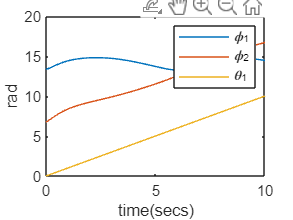

theta_vals = omega*time;
plot(time,phi_1_vals,time,phi_2_vals,time,theta_vals);

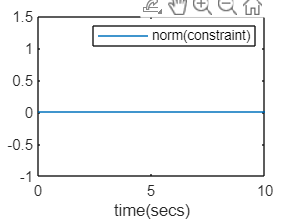

const_vals = zeros(size(time));
for i = 1:size(time)
    const_vals(i) = norm((vpa(subs(cons,[phi_1,phi_2,theta_1],[phi_1_vals(t),phi_2_vals(t),theta_vals(t)]))));
end
plot(time,const_vals)

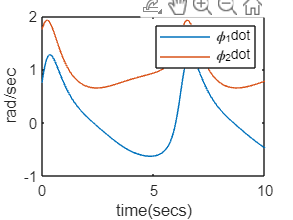

plot(time,phi_1d_vals,time,phi_2d_vals);

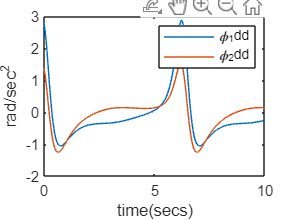

plot(time,phi_1dd_vals,time,phi_2dd_vals);

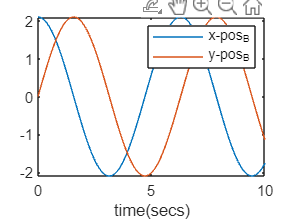


plot(time,a*cos(theta_vals),time,a*sin(theta_vals));

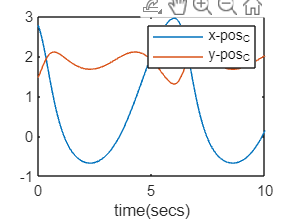

plot(time,d+(c*cos(phi_1_vals)),time,a*sin(phi_1_vals));

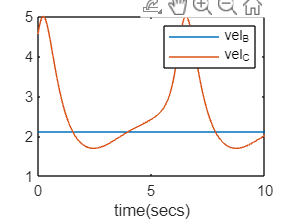


plot(time,repelem(a*omega,size(time,1)),time,c*phi_2d_vals);

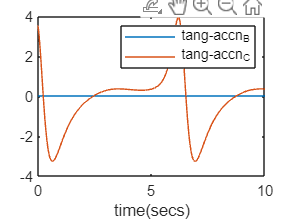

plot(time,zeros(size(time)),time,c*phi_2dd_vals);

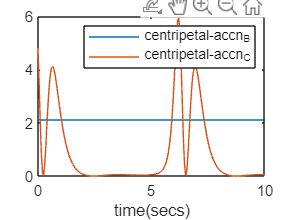


plot(time,repelem(omega*omega*a,size(time,1)),time,(phi_2dd_vals.*phi_2dd_vals)*c);

function [phi1,phi2] = Pose_NR(qinit,jacU,jacV,cons,thet,phi_1,phi_2,theta_1)

qiter = qinit;
tol = 10^(-6);
i = 1;
while true
    
    del_qi = -(vpa(subs(jacU,[phi_1,phi_2,theta_1],[qiter(1),qiter(2),thet])))\(vpa(subs(cons,[phi_1,phi_2,theta_1],[qiter(1),qiter(2),thet])));
    if all(abs(del_qi)<tol)
        break;
    end
    i = i+1;
    qiter = qiter + del_qi;
end
phi1 = qiter(1);
phi2 = qiter(2);

end
